# Derivative Rules for Transcendental Functions

[⇦ Overview](matlab: OpenOverview)

For some common functions, applying the limit definition of the derivative requires more complicated limit proofs than those required for polynomials. This script presents the derivatives of sines, cosines, exponentials and natural logarithms through numerical approximation.

**Startup Instructions**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 If you find the MATLAB coding in this script to be challenging, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## What is a Transcendental Function?

Have you encountered transcendental numbers like $e\approx 2.71828182459046$ or $\pi \approx 3.141592653589793$? They are called *transcendental* because they are not *algebraic,* that is they are not a root of any finite degree polynomial equation with integer coefficients. All rational numbers are algebraic, e.g., $x = \frac{p}{q}$ is a root of $y = qx-p$, but many irrational numbers are algebraic as well, e.g., $x=\sqrt{5}$ is a root of $y=x^2-5$. Despite the lack of a related finite degree polynomial equation, you can still approximate transcendental numbers by their sequence of decimal expansions, e.g., 3, 3.1, 3.14, 3.141, 3.1415, 3.14159, etc. A *transcendental function* is a function that you can approximate by a sequence of polynomial functions, but that is not the solution to a polynomial equation itself. The most common transcendental functions are the exponential, logarithm, and trigonometric functions.

## Numerical Approximation

Recall the graphical approach to understanding the limit definition of the derivative as [approximation by secant lines](matlab:open('./derivativeDefinition.mlx')) approaching a tangent line. This script will build on that same idea by identifying adjacent points separated by a small step size on a curve and evaluating the slope of the secant line through those points. As the step size gets smaller, the slope of the secant line will numerically approximate the slope of the tangent line. There are entire courses and research programs devoted to numerical analysis that ask and answer questions about how best to describe and compute these approximations, but that is beyond the scope of this script.

## Trigonometric Functions

Trigonometric functions are the family of functions that relate the ratios of sides to the angles in right triangles. 

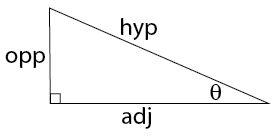

The abbreviations are

 opp = "length of the side opposite the angle $\theta$",                                  

adj = "length of the side between the right angle and the angle $\theta$", 

and 

hyp = "length of the hypotenuse".                                                      

### Sines & Cosines

The function $y = \sin(\theta)$ tracks the ratio $\frac{\text{opp}}{\text{hyp}}$. 

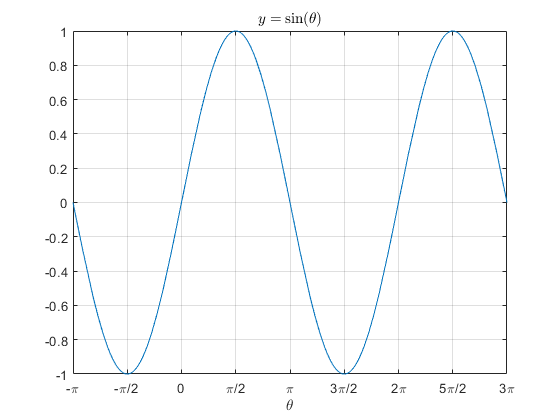

The function $y=\cos(\theta)$ tracks the ratio $\frac{\text{adj}}{\text{hyp}}$. 

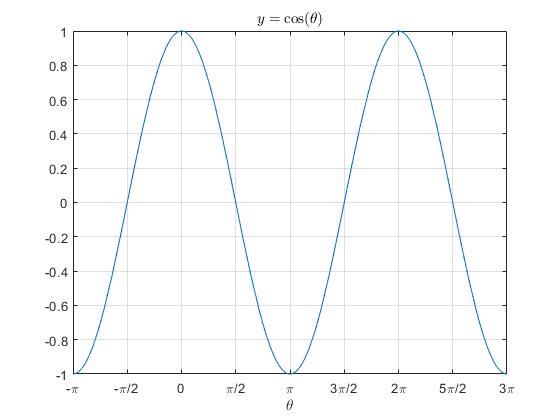

By placing a right triangle into a unit circle, the intimate relationship between sines and cosines becomes clear.

This is shown in [.mp4 animation](matlab:open('./unitCircleAnimation.mp4')) or by generating the animation below: 

 
unitCircleAnimation();

  **Pro-tip**. If this script is running too slowly, you can click the **Stop** button in the **Live Editor **tab. That will terminate the script.

### Derivative of Sine

** Activity. **Let's try to determine the derivative $\frac{dy}{d\theta}$ of $y=\sin(\theta)$ by computing its numerical approximation. First, let's pick a step size $h$ to use in the difference quotient: 

$\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$,

and graph the result:

h = 0.2;                % User-defined step size set to disallow h = 0, default 0.2
                       % Run this section
if ~exist("sinTHandle","var") || ~isvalid(sinTHandle)
    figure                                      % Initialize a figure
    [sinsHandle,sinmptHandle,sinTHandle] = graphApproxDer(@(t)sin(t),"sin",h,[-pi 3*pi]);
    % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    updateDerApprox(@(t)sin(t),"sin",h,[-pi 3*pi],sinsHandle,sinmptHandle,sinTHandle)
end

  **Try**. Make the value of the step size larger and smaller and observe the impact on the approximate derivative of $\sin(\theta)$that is shown in the graph above.

** Exercise 1**. Consider the approximate derivative $\frac{d}{d\theta}\left[\sin(\theta)\right]$ that is graphed above.

- Could the derivative be a polynomial function? Why or why not?

poly = "idk";         % User-defined answer to Question 1.1
% If the answer has changed from the default, "I don't know", display
% appropriate feedback.
if poly == "yes"
    disp("All polynomials p(t) diverge towards positive or negative infinity as p goes to infinity.")
    disp("That is not true of this derivative. It is not a polynomial.")
elseif poly == "no"
    disp("That is correct.")
    disp("This cannot be a polynomial because it does not have the correct limiting behavior.")
end

         2. Does the derivative have any asymptotes? Why or why not? If there are any asymptotes, what are they?

asymptotes = "idk";   % User-defined answer to whether there are any asymptotes and of which type
yasymp = 0.5;       % If there is a horizontal asymptote, the user should set the value here
xasymp = 0.5;       % If there is a vertical asymptote, the user should set the value here
% In this case there are no asymptotes, but for symmetry with later
% questions the option to define them is included here as well
% If the answer has changed from the default, "I don't know", display
% appropriate feedback.
if (asymptotes == "yHoriz") || (yasymp ~= 0.5)
    disp("No, there is not a horizontal asymptote. Please try again.")
elseif (asymptotes == "yVert") || (xasymp ~= 0.5)
    disp("No, there is not a vertical asymptote. Please try again.")
elseif asymptotes == "no"
    disp("Correct. The derivative does not have any asymptotes.")
end

         3. Is the derivative periodic? Why or why not? If it is periodic, what is the period and what is the peak amplitude?

periodic = -1;   % User-defined answer to whether the derivative is periodic
% Interact with the user based on their choices, with specific messages
% tagged to the default options which have been chosen to be incorrect
if periodic == 1
    disp("Yes, this derivative is periodic. Please set the correct period and amplitude:")
    period = pi;          amplitude = 0.5;
    if period == 2*pi
        disp("The period is correct.")
    elseif abs(period-2*pi) < .0033    % Check for an answer based on 3.14 rather than pi
        disp("Please use the exact value pi rather than the approximation 3.14.")
    elseif period == pi
        disp("The period is not pi.")
        disp("Dashed blue lines show the proposed period.")
    else
        disp("The period is incorrect. Please try again.")
        disp("Dashed blue lines show the proposed period.")
    end
    if amplitude == 1
        disp("The amplitude is 1, that is correct.")
    elseif abs(amplitude-1) < .01       % Prompt the user to find the exact value
        disp("Please be more precise. The amplitude is an integer.")
    elseif amplitude == 1/2
        disp("The amplitude is not 1/2.")
        disp("Dotted red lines show the proposed amplitude.")
    else
        disp("The amplitude is incorrect. Please try again.")
        disp("Dotted red lines show the proposed amplitude.")
    end
    if ~exist("h","var")
        h = .2                                     % Set the default step size if not user-defined
    end
    graphApproxDer(@(t)sin(t),"sin",h,[-pi 3*pi]); % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
    if abs(amplitude)>1                   % Resize the plot to show the proposed amplitude line
        ylim([-1.1 1.1*abs(amplitude)]);
    end
    hold on
    xline(0,"b--")                        % Plot the proposed period at x=0 and x=period, dashed blue line
    xline(period,"b--")
    yline(0,"r:")                         % Plot the proposed amplitude at y=0 and y=amplitude, dotted red line
    yline(amplitude,"r:")
    hold off
elseif periodic == 0                      % If solution is incorrect, offer a hint
    disp("No, that is incorrect. Does this function ever repeat?")
end

** Exercise 2**. Taking into account the results of Exercise 1, the derivative $y'(\theta)$ should be a function that you recognize. Use the independent variable name `t for `$\theta$, what is the derivative of `sin(t) `with respect to `t`?

derGuess = @(t)t;  % User-defined anonymous symbolic function, default @(t)t
                            % Run this section
checkSinDer(derGuess)                 % checkSinDer is defined in Helper Functions
% checkSinDer takes the function handle derGuess and checks whether it is equivalent
% to the derivative of sin(t)

### Derivative of Cosine

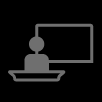** Activity**. Try to determine the derivative $\frac{dy}{d\theta}$ of $y=\cos(\theta)$ by computing its numerical approximation just as you did for $\sin(\theta)$ up above. First, pick a step size $h$ to use in the difference quotient, $\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$, and graph the result again.

h = 0.2;               % User-defined step size, default h = 0.2
                           % Run this section
if ~exist("cosTHandle","var") || ~isvalid(cosTHandle)
    figure                                     % Initialize a figure
    [cossHandle,cosmptHandle,cosTHandle] = graphApproxDer(@(t)cos(t),"cos",h,[-pi 3*pi]);
    % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    updateDerApprox(@(t)cos(t),"cos",h,[-pi 3*pi],cossHandle,cosmptHandle,cosTHandle)
end

Remember that the derivative of $y=\sin(\theta)$ was $y' = \sin\left(\theta+\frac{\pi}{2}\right)$. It appears that the derivative of $y=\cos(\theta)$ is also a sinusoidal function with the same amplitude. Use the slider to test values of the phase shift $\phi$ to determine the function $\frac{d}{d\theta}\left[\cos(\theta)\right] = \cos(\theta+\phi)$. You want the solid blue line to cover the black points.

mult = 0;            % User-defined multiplier, default mult = 0
if ~exist("h","var")
    h = .2                                      % If not user-defined, set default h = 0.2
end
figure                                          % Initialize a figure
graphApproxDer(@(t)cos(t),"cos",h,[-pi 3*pi]);  % graphApproxDer is defined in Helper Functions
% graphApproxDer plots a function and calculates and plots its numerical
%      derivative with step size h
hold on
graphDerGuess(@(t)cos(t),mult)                  % graphDerGuess is defined in Helper Functions
% graphDerGuess plots the function given by fh with a phase shift of mult*pi
%      and adds annotation noting that \phi = mult*pi on the plot
%      in the lower left hand quadrant of the plot
hold off

Once you have chosen the best possible function to fit the approximate derivative, you can check your result here using `t` as your independent variable. If you wish, you may also use `phi` for the value $\phi$ you set above or `pi` for the value $\pi$ :

phi = mult*pi;                                 % User-defined multiplier based on the slider mult above
cosDerGuess = @(t)t*phi*pi;        % User-defined anonymous function, default @(t) t*phi*pi
                                     % Run this section
checkCosDer(cosDerGuess)                       % checkCosDer is defined in Helper Functions
% checkCosDer compares the derivative of cos(t) to fh(t) and prints a message
%      of success or failure using disp()

  **Try **

What happens if you look at the derivative of $y=\sin(c\theta)$ for some constant value $c$?

h = 0.021;               % User-defined step size, default h = 0.021
c = 3;                       % User-defined constant (numerical) value, default c=3
if abs(c)>1
    bds = [-pi 3*pi];
else
    bds = [-pi abs(3/c)*pi];
end
                            % Run this section
if ~exist("sincTHandle","var")||~isvalid(sincTHandle)
    figure                                      % Initialize a figure
    [sincHandle,sincmptHandle,sincTHandle,sincFH] = graphApproxDer(@(t)sin(c*t),"sin",h,bds);
    % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
    sincTHandle.String = "$y = \sin(c\theta)$ with $c = $" + c;
    legend("$\sin(c\theta)$","Selected Points","Difference Quotient","AutoUpdate","off")
    ax = sincTHandle.Parent;
    if abs(1.1*c)>1.1
        ax.YLim = [-abs(1.1*c) abs(1.1*c)];
    else
        ax.YLim = [-1.1 1.1];
    end
else
    updateDerApprox(@(t)sin(c*t),"sin",h,bds,sincHandle,sincmptHandle,sincTHandle)
    if c == round(c,0)
        sincStr = compose("$y = \\sin(%.0f\\theta)$",c);
    elseif c == round(c,1)
        sincStr = compose("$y = \\sin(%.1f\\theta)$",c);
    elseif c == round(c,2)
        sincStr = compose("$y = \\sin(%.2f\\theta)$",c);
    else
        sincStr = "$y = \sin(c\theta)$ with $c = $" + c;
    end
    sincTHandle.String = sincStr;
    sincFH.Function = sin(c*t);
    if abs(1.1*c)>1.1
        ax.YLim = [-abs(1.1*c) abs(1.1*c)];
        ax.XLim = [-pi 3*pi];
    else
        ax.YLim = [-1.1 1.1];
        ax.XLim = [-pi abs(3/c)*pi];
    end
end

 **Reflect**

- What is the derivative $y'(\theta)$ for the function $y = \sin(7\theta)$? What is the derivative $y'(\theta)$ for the function $y=\sin(-.36\theta)$?

- What do you think is the derivative $\frac{dy}{d\theta}$ for the function $y = \cos(c\theta)$ for some constant value $c$? Why?

- What do you think is the derivative $\frac{d}{d\theta}\left[\sin(\theta + \phi)\right]$ for some constant value $\phi$? Why?

## Second Derivatives

As discussed in [derivativeDefinition.mlx](matlab:open('./derivativeDefinition.mlx')), the derivative is a linear operator. In particular, since the derivative of a function is another function, it is possible to take several derivatives in sequence:

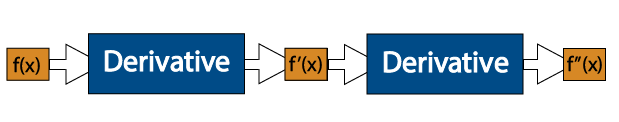

Let's assume the units of $f(x)$ are frogs and the units of $x$ are feet. Then 

$f(x)$ is the number of frogs                                                        

$f'(x)$ is the number of frogs per foot ($\frac{\text{frogs}}{\text{foot}}$)                               

$f^{\prime \prime}(x)$ is the number of frogs per square foot ($\frac{\text{frogs/foot}}{\text{foot}} = \frac{\text{frogs}}{\text{foot}^2}$)

 **Notation for Higher Order Derivatives**

Prime Notation

$f(x)$, $f'(x)$, $f''(x)$, $f'''(x)$, $f^{(iv)}(x)$, $f^{(v)}(x)$, $\ldots$, $f^{(n)}(x)$

Differential Notation

$f(x)$,     $\frac{df}{dx}$,     $\frac{d^2f}{dx^2}$,     $\frac{d^3f}{dx^3}$,     $\frac{d^4f}{dx^4}$,     $\frac{d^5f}{dx^5}$,     $\ldots$,     $\frac{d^nf}{dx^n}$

Operator Notation

$f(x)$, $\frac{d}{dx}[f]$, $\frac{d}{dx}\left[\frac{d}{dx}[f]\right] = \frac{d^2}{dx^2}[f]$, $\frac{d}{dx}\left[\frac{d}{dx}\left[\frac{d}{dx}[f]\right]\right] = \frac{d^3}{dx^3}[f]$, $\ldots$, $\frac{d^n}{dx^n}[f]$

** Exercise 3**.

The notation for the $n^{\text{th}}$ derivative of $g$ with respect to $y$ is $\frac{d^ng}{dy^n}$ or $g^{(n)}(y)$ or $\frac{d^n}{dy^n}\left[g\right]$.

If the units of $g$ are

gUnits = "";            % User-defined string labeling units of dependent variable

and the units of $y$ are

yUnits = "";            % User-defined string labeling units of independent variable
                            % Run section
if gUnits ~= "" && yUnits ~= ""           % Check for non-empty unit labels
    [n,opts] = setOptions(gUnits,yUnits); % setOptions is defined in Helper Functions
    % setOptions sets up the unit options and selects the power n
    % for reference use in the drop-down menu dngdyn below
elseif (gUnits ~= "") && (yUnits == "")   % Prompt the user to enter a string in yUnits
    disp("You need to set values for the units of y to complete Exercise 3.")
elseif (gUnits == "") && (yUnits ~= "")   % Prompt the user to enter a string in gUnits
    disp("You need to set values for the units of g to complete Exercise 3.")
else                                      % Prompt the user to enter strings in both gUnits and yUnits
    disp("You need to set values for the units of g and the units of y to complete Exercise 3.")
end

dngdyn = 0;  % User-defined answer to Exercise 3, default "Unknown" with value 0
if dngdyn == 0                  % If the user has not changed the default value
    disp("It is possible to determine the units of the derivative.")
end
% Use a try/catch structure to replace "Unknown variables" error with constructive feedback
try                          % If the code inside the try generates an error, the catch block
    checkGYUnits(dngdyn,n);  % executes rather than terminating the script with an error that
catch                        % throws the user out of "Hide Code" mode
    warning("You need to generate the problem in Exercise 3 before you can solve it.")
end

###  Application: Springs

Consider a simple mass-spring system with mass $m$ and stiffness coefficient $k>0$:

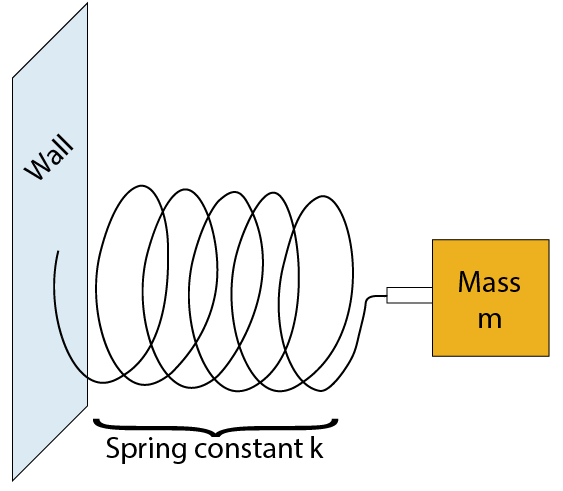

Then the motion of the mass as a function of the horizontal displacement $x = p(t)$ is given by a differential equation (that is an equation involving derivatives): 

                                         
$$\text{Force} = -k\cdot \left(\text{Displacement from Equilibrium}\right)$$



$$\text{Mass} \times \text{Acceleration} = -k\cdot p(t)$$
                            


$$m\cdot \frac{d}{dt}\left[\frac{d}{dt}\left[p(t)\right]\right] = -k\cdot p(t)$$
                      

$\frac{d^2p}{dt^2} = -\frac{k}{m}p(t)$,

where the force generated by the spring is acting in opposition to the displacement from equilibrium.  Thus, if $p(t)>0$, then the acceleration of the mass is in the negative direction towards zero and if $p(t)<0$, then the acceleration of the mass is in the positive direction towards zero. The equilibrium position, where the mass will stay at rest if it starts at rest is $p(t)=0$.

** Exercise 4**. Let's consider a case where $k=m=1$. This simplifies the differential equation to $\frac{d^2p}{dt^2} = -p(t)$. Check whether any functions that you know satisfy this differential equation, that is if you calculated the second derivative $p''(t)$ that is the same function as $p(t)$ originally multiplied by -1.

- $p(t) = x^n$ for any constant $n$

- 
$$p(t) = \sin(t)$$


- 
$$p(t) = \cos(t)$$


- 
$$p(t) = 3\sin(t)-7\cos(t)$$


Select the corresponding check box if $p''(t) = -p(t)$ and leave unselected if $p''(t)\neq -p(t)$.

% User-selected booleans to identify which statements are true or false,
% corresponding to Exercise 4, Statements 1-4.
one = false; two = false; three = false; four = false;
checkEqns(one,two,three,four);  % checkEqns is defined in Helper functions
% checkEqns checks the truth of one, two, three, and four and prints feedback
                 % Run this section

 **Reflect**

- Why are there multiple different functions that all solve the same differential equation?

- Can you sketch a solution to a differential equation even if you don't know how to write the solution as a function? Why or why not?

- Can you find a solution to the differential equation when $k$ and $m$ are not both 1? For instance, what about $\frac{d^2p}{dt^2} = -4p$? 

## Exponential Functions

The full beauty of exponential functions only starts to come into focus when you consider them in the realm of calculus. 

  **Pro-tip**. In MATLAB, use the command `exp(2*x)` for $e^{2x}$.

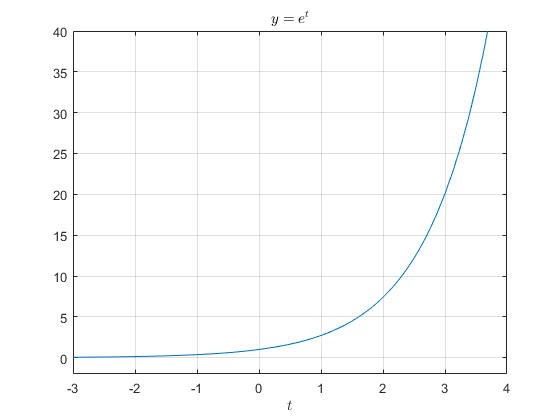

** Demonstration**. Take the same approach you did with $y=\cos(\theta)$ and compute and graph some values of the difference quotient for $f(t) = e^t$,

$\text{Difference Quotient} = \frac{e^{t+h}-e^{t}}{h} = e^t\left(\frac{e^h-1}{h}\right)$.

h = 0.2;          % User-defined step size, default h = 0.2
                      % Run this section
if ~exist("expTHandle","var") || ~isvalid(expTHandle)
    figure                                % Initialize a figure
    [expsHandle,expmptHandle,expTHandle] = graphApproxDer(@(t)exp(t),"exp",h,[-3 4]);
    % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    updateDerApprox(@(t)exp(t),"exp",h,[-3 4],expsHandle,expmptHandle,expTHandle)
end

  **Try **Set some different values of `h` using the slider. Then check your hypothesis. Remember to use `t` as the independent variable.

myGuess = @(t) exp(t);   % User-defined prediction of the derivative of exp(t)
                            % Run this section
checkExpDer(myGuess);                 % checkExpDer is defined in Helper Functions
% checkExpDer compares myGuess to the derivative of exp(t)

### ** Application: Population Growth**

Say there is a population of bunnies like these:

              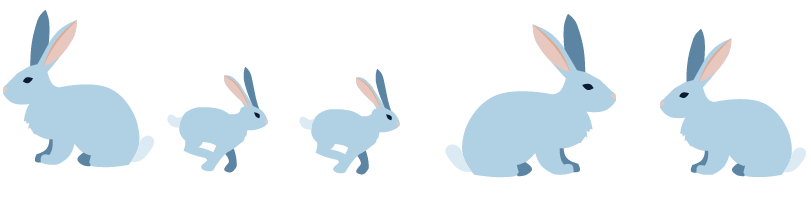    

If the number of bunnies at time $t$ in years is modelled by the function $B(t)$, then the rate of change of the number of bunnies over time is given by the derivative $\frac{dB}{dt}$ with units of bunnies per year. Say at time $0$ the bunny population is $100$, what is happening to the bunny population over time if $\frac{dB}{dt} = B(t)$?

 **Reflect**

- What type of function is its own derivative? How can you set the initial value to 100?

- What does this imply about the bunny population over the long term? 

- In what ways is this model realistic? In what ways is it unrealistic? 

** Activity**. The difference quotient approximation to the derivative can be used to approximate the solution to a differential equation with a known initial value. Say there are 100 bunnies to start, so $B(0)=100$. Each year, assume all the bunnies reproduce once. Assuming that the bunny population is half male and half female and that the average litter size is $k$, that means that the number of new baby bunnies is given by $\frac{dB}{dt} = k\left(\frac{B(t)}{2}\right)$, so 

$\frac{B(t+h)-B(t)}{h} \approx k\left(\frac{B(t)}{2}\right)$. 

Thus, 

$B(t+h) = B(t) + hk\left(\frac{B(t)}{2}\right)$.

  **Try**. The following code implements the model $B(t+h) = B(t)+k\left(\frac{B(t)}{2}\right)$ with $h=1$ year for `tEnd` years, using the new bunny population each time. Therefore, 


$$B(1) = B(0+1) = B(0)+k\left(\frac{B(0)}{2}\right) = 100 + 50k$$
                                                        


$$B(2) = B(1+1) = B(1)+k\left(\frac{B(1)}{2}\right) = 100+50k + k\left(50+25k\right) = 100+100k+25k^2$$



$$\vdots$$
                                                                                                                  


$$B(\text{tEnd}) = B(\text{tEnd}-1)+k\left(\frac{B(\text{tEnd}-1)}{2}\right)$$
                                                                               

The code looks like this:

Run this code with different choices for litter size `k` and the total number of years, `tEnd, `and compare the number of bunnies to the reference function $y(t) = 100e^t$, which starts at the same value and grows exponentially. How do your results change with different values for `k`? For `tEnd`?

k = 5;        % User-defined litter size, default k = 5
tEnd = 5;     % User-defined year tEnd, default tEnd = 5
                      % Run this section
tdata = 0:tEnd;             % Set up a time vector
Bdata = size(tdata);        % Initialize a vector to use for the bunny population
Bdata(1) = 100;             % Set B(0)=100
for j = 1:tEnd
    Bdata(j+1) = Bdata(j) + k*(Bdata(j)/2);    % Update the population at each timestep
end
figure                            % Initialize a figure
plot(tdata,Bdata,"b*-")           % Plot the calculated bunny population versus time
hold on
plot(tdata,100*exp(tdata),"r*-")  % Add the plot of 100*e^t versus time
hold off
% Add a title, labels, and a legend to the plot
title("Modelling the Bunny Population")
xlabel("t (years)")
ylabel("# of Bunnies")
legend("Bunny Model with k = " + k, "y = 100e^t","Location","northwest")

 **Reflect**.

- Why are the two functions different?

- Which function is growing faster? Why?

- Can you find a parameter `k` where the Bunny Model is growing slower than $100e^t$? Can you find a parameter `k` where the Bunny Model is growing faster than $100e^t$? 

#### Refining the Population Model

As you can see, the first Bunny Population Model is very coarse, resulting in piecewise defined graphs that do not look like smooth curves because you are only checking on the bunny population once each year. In fact, rabbits mature very quickly and can have several litters of babies each year, so let's allow a bit more flexibility with the time step with the same `tEnd` as above:

if ~exist("k","var")            % Set up the default parameters
    k = 5;                      % in case the previous section hasn't run, default k = 5
end
if ~exist("tend","var")         % Set up the default parameters
    tEnd = 5;                   % in case the previous section hasn't run, default tEnd = 5
end
dt = 0.25; % User-defined time step between litters (in years), default dt = 0.25
 
tData = 0:dt:tEnd;              % Set up a time vector with step size dt
BunnyData = size(tData);        % Initialize a vector for the bunny population
BunnyData(1) = 100;             % Set B(0)=100
for j = 1:length(tData)-1
    BunnyData(j+1) = BunnyData(j)+dt*(k/2)*BunnyData(j);   % Update the population at each timestep
end
figure                          % Initialize a figure
plot(tData,BunnyData)           % Plot the calculated bunny population versus time
hold on
syms t
fplot(100*exp(t),[0 tEnd])      % Add a plot of 100*e^t versus time
hold off
title("Modelling the Bunny Population")
xlabel("t (years)")
ylabel("# of Bunnies")
if exist("Bdata","var") && exist("tdata","var") % Check if the basic bunny model has already been run
    hold on
    scatter(tdata,Bdata,"filled")               % Add a scatter plot of the bunny population with dt=1
    legend("Numerical Model with k = " + k + " and step size " + dt,"y = 100e^t","Numerical " + ...
        "Model with k = " + k + " and step size 1","Location","northwest")
    hold off
else                    % Remind the user to run the previous section and label only the current plots
    disp("Run the Bunny Model before this section to compare the two.")
    legend("Numerical Model with k = " + k + " and step size " + dt,"y = 100e^t","Location","northwest")
end


 **Reflect**

- What is the impact on the model as the step size between generations approaches 0? Is it realistic to allow the step size to approach 0 here? Why or why not?

- What type of function solves the differential equation $\frac{dy}{dx} = ky$ for $k$ a constant? Does it matter what $k$ is?

- What type of function solves the differential equation $\frac{dy}{dx} = kx$ for $k$ a constant? Does it matter what $k$ is?

- What is the derivative $\frac{d}{dt}\left[e^{at}\right]$ for constant $a$? 

## Logarithms

A logarithm is the inverse operation to exponentiation. As noted above, calculus identifies a special role for an exponent with base $e$, so there is a corresponding role for the natural logarithm $\ln(t) = \log_e(t)$. There is one additional complication with logarithms because the domain of a logarithm is $(0,\infty)$. 

** Activity**. Predict the type of function that will be the derivative of a natural logarithm and then run the code to generate a graph of the approximate derivative of $\ln(t)$.

h = 0.1;            % User-defined step size h, default 0.1
    % Run this section
if ~exist("logTHandle","var") || ~isvalid(logTHandle)
    figure                                  % Initialize a figure
    [logsHandle,logmptHandle,logTHandle] = graphApproxDer(@(t)log(t),"ln",h,[0 8]);
    % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    updateDerApprox(@(t)log(t),"ln",h,[0 8],logsHandle,logmptHandle,logTHandle)
end

  **Try **Set the step size to various values and predict the function that is the derivative of $\ln(t)$. 

** Exercise 5**. Consider the graph of the approximate value of the derivative $\frac{d}{dt}\left[\ln(t)\right]$.

- Could the derivative be a polynomial function? Why or why not?

poly = "no";   % User-defined answer to Exercise 5.1
% Interact with the user based on their choices
if poly == "yes"
    disp("All polynomials p(t) diverge towards positive or negative infinity as p goes to infinity.")
    disp("That is not true of this derivative. It is not a polynomial.")
elseif poly == "no"
    disp("That is correct.")
    disp("This cannot be a polynomial because it does not have the correct limiting behavior.")
end

       2. Does the derivative have any asymptotes? Why or why not? If there are any asymptotes, what are they?

asymptotes = "idk"; % User-defined answer to Exercise 5.2
% Interact with the user based on their choices
if asymptotes == "yHoriz"
    disp("Yes, there is a horizontal asymptote.")
    disp("Adjust the horizontal asymptote to the correct value:")
    yasymp = 3;     % As the user updates this value, the section will run again
    xasymp = 3;     % As the user updates this value, the section will run again
    graphApproxDer(@(t)log(t),"ln",h,[0 8]);     % graphApproxDer is defined in Helper Functions
    % graphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
    hold on
    plot([0 8],[yasymp yasymp],"b--");  % Plot the proposed horizontal asymptote for reference
    % Set up the format of the title string
    formatTitle = "Approximating the derivative of $y = \\%s(t)$ with step size $h=%.2f$";
    if ~exist("h","var")
        h = 0.1;                       % If necessary, set the default value for the step size
    end
    str = compose(formatTitle,"ln",h); % Include the name of the function and the step size
    title(str,"Asymptote $y=$" + yasymp,"Interpreter","latex")
    hold off
    if yasymp == 0
        disp("That is correct, the horizontal asymptote is at y=0.")
    end
elseif asymptotes == "yVert"
    disp("No, there is not a vertical asymptote. Please try again.")
elseif asymptotes == "no"
    disp("Yes, there is an asymptote. What type is it?")
end

        3. Is the derivative periodic? Why or why not? If it is periodic, what is the period and what is the amplitude?

periodic = -1;   % User-defined answer to Exercise 5.3
% Interact with the user based on their choices
period = "2*pi";          amplitude = "1";
if periodic == 1
    disp("No, this derivative is not periodic. Please try again.")
elseif periodic == 0
    disp("That is correct. This derivative is not periodic.")
end

       4. Putting all of the facts established in Exercise 5, parts 1-3 together, identify the functional family of the derivative of the natural logarithm. 

% User-defined answer to "What type of function is the derivative of a natural logarithm?
lnDerGuessType = "unknown";
checkLnDerGuessType(lnDerGuessType);  % checkLnDerGuessType is defined in Helper Functions
% checkLnDerGuessType plots a best-fit curve of form lnDerGuessType and provides
% written feedback to the function type selected and information about the goodness of fit

 **Reflect**

- Use numerical approximation or logarithm rules to determine the derivative $\frac{dy}{dx}$ of $y = \ln(cx)$ where $c$ is a constant. Does this match what you found for the other functions? Why or why not?

- What do you find with different choices for Exercise 5, part 4?

### Practice App

If you would prefer to practice in the Calculus Flashcards app, you can start it by clicking on the image below. You should set it for "Derivatives of Functions" in the Derivatives section. The app will open in a new window.

[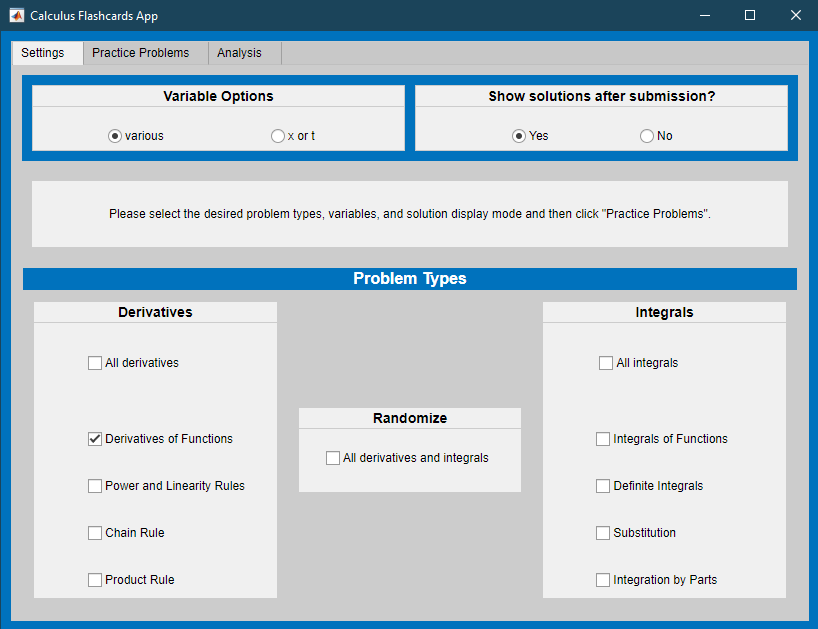](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function checkSinDer(fh)
% checkSinDer takes a function handle and checks whether it is equivalent
% to cos(t)
%
% fh is a function handle
syms t                             % Create a symbolic variable t
if cos(t) == fh(t)                 % Compare the symbolic function cos(t) and fh(t)
    disp("Correct.")               % If they are identical, display "Correct"
elseif cos(t) == simplify(fh(t))   % If they are equivalent, display additional feedback
    disp("Correct. It is more common to write cos(t), however.")
else                               % If the answer is incorrect, include a hint
    disp("Incorrect. What other sinusoidal functions do you know?")
end
end

function [sHandle,mptHandle,gTHandle,fHandle]=graphApproxDer(fh,fs,dt,bds)
% graphApproxDer plots a function and calculates and plots its numerical
% derivative with step size dt
%
% fh is a function handle to the function to be graphed
% fs is the same function name as a string
% dt is the step size
% bds is a 1x2 vector [lower_bound upper_bound]
syms t                 % Create a symbolic variable t
figure                 % Create a new figure
fHandle = fplot(fh(t),bds);      % Plot the function fh(t) symbolically over the domain bds
if bds(1) == -pi       % Label the plot for trigonometric functions
    formatTitle = "Approximating the derivative of $y = \\%s(\\theta)$ with step size $h=$%.2f";
    xticks(-pi:pi/2:3*pi)
    xticklabels(["-\pi","-\pi/2","0","\pi/2","\pi","3\pi/2","2\pi","5\pi/2","3\pi"])
    formatLegend1 = "$\\%s(\\theta)$";
    formatLegend2 = "Difference Quotient: $\\left(\\theta, \\frac{\\%s(\\theta+h)-\\%s(\\theta)}{h}\\right)$";
    formatPts = "Selected Points: $\\left(\\theta, \\%s(\\theta)\\right)$";
else                   % Label the plot for exponential/logarithmic functions
    formatTitle = "Approximating the derivative of $y = \\%s(t)$ with step size $h=$%.2f";
    xticks(linspace(bds(1),bds(2),bds(2)-bds(1)+1));
    xticklabels(bds(1):bds(2));
    formatLegend1 = "$\\%s(t)$";
    formatLegend2 = "Difference Quotient: $\\left(t,\\frac{\\%s(t+h)-\\%s(t)}{h}\\right)$";
    formatPts = "Selected Points: $\\left(t,\\%s(t)\\right)$";
end
% Annotate the plot with a title, axes labels, and legend
graphTitle = compose(formatTitle,fs,dt);
line1 = compose(formatLegend1,fs);
line2 = compose(formatLegend2,fs,fs);
pts = compose(formatPts, fs);
gTHandle = title(graphTitle,"Interpreter","latex");
tVals = bds(1):dt:bds(2);
yVals = fh(tVals);
hold on
sHandle = scatter(tVals,yVals,100,"r.");  % Plot the points used for the numerical approximation of the derivative
hold off
derVals = (yVals(2:end)-yVals(1:end-1))/dt; % Compute the numerical derivative using the difference quotient
mdPts = (tVals(2:end)+tVals(1:end-1))/2;    % Determine the interval midpoints for graphing
hold on
mptHandle = plot(mdPts,derVals,"k.");       % Plot (midpoint, slope of secant line for that interval)
legend(line1,pts,line2,...
    "Interpreter","latex","Location","southoutside","AutoUpdate","off")
hold off
end

function updateDerApprox(fh,fs,dt,bds,sHandle,mptHandle,gTHandle)
if bds(1) == -pi       % Label the plot for trigonometric functions
    formatTitle = "Approximating the derivative of $y = \\%s(\\theta)$ with step size $h=$%.2f";
else                   % Label the plot for exponential/logarithmic functions
    formatTitle = "Approximating the derivative of $y = \\%s(t)$ with step size $h=$%.2f";
end
% Annotate the plot with a title, axes labels, and legend
gTHandle.String = compose(formatTitle,fs,dt);
tVals = bds(1):dt:bds(2);
yVals = fh(tVals);
sHandle.XData = tVals;                      % Update the points
sHandle.YData = yVals;
derVals = (yVals(2:end)-yVals(1:end-1))/dt; % Compute the numerical derivative using the difference quotient
mdPts = (tVals(2:end)+tVals(1:end-1))/2;    % Determine the interval midpoints for graphing
mptHandle.XData = mdPts;                    % Update the midpoint line
mptHandle.YData = derVals;
end

function graphDerGuess(fh,mult)
% graphDerGuess plots the function given by fh with a phase shift of mult*pi
%               and adds annotation noting that \phi = mult*pi on the plot
%               in the lower left hand quadrant of the plot
%
% fh is a function handle and mult is a number
syms t                       % Create a symbolic variable t
% Plot y=(fh(t+mult*pi)) symbolically on the domain [-pi,3*pi] with a
% blue line of width 2
fplot(fh(t+mult*pi),[-pi 3*pi],"b-","LineWidth",2)
dim = [.22 .25 .2 .2];       % Define the relative location (.22,.25) for the corner of a square box of side .2
[num,den] = rat(abs(mult));  % Find the numerator and denominator of the rational form of |mult|
if mult < 0                  % Fix the sign of the numerator to match the sign of mult
    num = -num;
end
% Print phi elegantly
if den ~= 1 && abs(num) ~= 1      % If mult is not an integer, nor a unit fraction
    formatStr = "$\\phi = \\frac{%d\\pi}{%u}$";
    str = compose(formatStr, num, den);
elseif den ~= 1 && num == 1  % If mult is a unit fraction
    formatStr = "$\\phi = \\frac{\\pi}{%u}$";
    str = compose(formatStr, den);
elseif den ~= 1 && num == -1  % If mult is a negative unit fraction
    formatStr = "$\\phi = \\frac{-\\pi}{%u}$";
    str = compose(formatStr, den);
elseif num == 1 && den == 1  % If mult is 1
    str = "$\\phi = \\pi$";
elseif num == -1 && den == 1 % If mult is -1
    str = "$\\phi = -\\pi$";
elseif num == 0              % If mult is 0
    str = "$\\phi = 0$";
else
    formatStr = "$\\phi = %d\\pi$";
    str = compose(formatStr,num);
end
% Annotate the plot with the value of phi in a white-bordered box at dim
annotation("textbox",dim,"String",str,"FitBoxToText","on",...
    "Interpreter","latex","EdgeColor",[1 1 1])
% Add a legend
legend(["$\cos(\theta)$" "Selected Points" "Approximate Derivative" "$\cos(\theta+\phi)$"],"Interpreter","latex")
end

function checkCosDer(fh)
% checkCosDer compares the function -sin(t) to fh(t) and prints a message
%             of success or failure using disp()
%
% fh is a function handle
syms t                             % Create a symbolic variable
if -sin(t) == fh(t)                % Check if -sin(t) == fh(t) as symbolic functions
    disp("Correct.")
elseif -sin(t) == simplify(fh(t))  % If -sin(t) is equivalent to fh(t) as symbolic functions
    disp("Correct. It is more common to write -sin(t), however.")
else                               % Display feedback
    disp("Incorrect. Try to find a better fit.")
end
end

function [n,gyOpts] = setOptions(gUnits,yUnits)
% gyOpts sets up the unit options and selects the power n
%
% gUnits are the units of the dependent variable
% yUnits are the units of the independent variable
n = randi([2 5]);              % Select a random integer from the set {2,3,4,5}
switch n                       % Set correct nth string for question text
    case 2
        nth = "second";
    case 3
        nth = "third";
    case 4
        nth = "fourth";
    case 5
        nth = "fifth";
end
formatgy = "%s/%s";            % Set up the format string for first derivatives
formatgy2 = "%s/%s^2";         % Set up the format string for second derivatives
formatgy3 = "%s/%s^3";         % Set up the format string for third derivatives
formatgy4 = "%s/%s^4";         % Set up the format string for fourth derivatives
formatgy5 = "%s/%s^5";         % Set up the format string for fifth derivatives
% Create strings for each option including the user-defined gUnits and yUnits
gyOpts = compose([formatgy,formatgy2,formatgy3,formatgy4,formatgy5],gUnits,yUnits);
% Ask the question
disp("If n = "+n+", then the nth ("+nth+") derivative of g with respect to y has units of:")
% Display the possible solutions
disp("Option 1: " + gyOpts(1))
disp("Option 2: " + gyOpts(2))
disp("Option 3: " + gyOpts(3))
disp("Option 4: " + gyOpts(4))
disp("Option 5: " + gyOpts(5))
end

function checkGYUnits(myAnswer,n)
% checkGYUnits checks myAnswer against the value n
%
% myAnswer is an integer in the range 1-5
% n is an integer in the range 2-5
if myAnswer == n           % Check if answer is correct
    disp("Correct!")
else                       % Give feedback and hint if answer is incorrect
    disp("Remember that every derivative involves dividing by the units of the independent variable.")
    disp("Please try again.")
end
end

function checkEqns(a,b,c,d)
% checkEqns checks the truth of a, b, c, and d and prints feedback
%
% a, b, c, and d are boolean values
if ~a && b && c && d     % Give feedback if the answer is correct
    disp("Correct!")
    disp(" Any linear combination of sines and cosines will be a solution to this differential equation.")
else                     % Give feedback and a hint if one or more of the answers is incorrect
    disp("Please check your derivatives.")
    disp("One of these functions does not work and three of them do.")
    disp("Why?")
end
end

function checkExpDer(myGuess)
% checkExpDer compares myGuess to exp(t)
%
% myGuess is a function handle
syms t                    % Create a symbolic variable
if myGuess == exp(t)      % If myGuess is correct, display feedback
    disp("Correct!")
    disp("All functions of the form a^x for constant a and variable x have derivatives")
    disp("that are multiples of the original, but only for e^x is that multiple 1.")
else                      % If myGuess is incorrect, display feedback, a graph, and a hint
    disp("Incorrect. What function does this look like?")
    disp("Remember that the MATLAB syntax for an exponential e^x is exp(x).")
    fplot(myGuess,[-3 4])
    hold on
    fplot(exp(t),[-3 4])
    hold off
    legend("My Guess","Derivative of $e^t$","Interpreter","latex","Location","northwest")
    ylim([-3 40])
end
end

function checkLnDerGuessType(myAnswer)
% checkLnDerGuessType plots a best-fit curve of form myAnswer and provides
%                     written feedback to the function type selected and
%                     information about the goodness of fit
%
% myAnswer is a string from the set
%          ["unknown" "exponential" "polynomial" "rational"]
tData = 0.01:.005:10;                    % Set up a row vector from 0.01 to 10 with step size .005
tData = tData';                          % Make it a column vector
tMid = (tData(2:end)+tData(1:end-1))/2;  % Find the midpoints of each interval for graphing
DQCalc = (log(tData(2:end))-log(tData(1:end-1)))/.005; % Calculate the slopes of the secants
switch myAnswer                          % Give feedback based on the user-solution
    case "unknown"                       % Default value, encourage effort
        disp("You can do better than that. The answer is a familiar type of function.")
        return
    case "exponential"                   % Feedback, including plot of an exponential best fit
        disp("No, the derivative of a logarithm is not an exponential function.")
        [fnFit,fnGoF] = fit(tMid,DQCalc,"exp1");
    case "polynomial"                    % Feedback, including plot of a degree 5 polynomial best fit
        disp("No, the derivative of a logarithm is not a polynomial.")
        [fnFit,fnGoF] = fit(tMid,DQCalc,"poly5");
    case "rational"                      % Feedback, including plot of a rational best fit
        disp("Yes, the derivative of a logarithm is a rational function.")
        [fnFit,fnGoF] = fit(tMid,DQCalc,"rat33","StartPoint",[0 1 0 0 0 0 0]);
end
% Graph the best fit of the chosen functional type
plot(fnFit,tMid,DQCalc)
ylim([-5 30]);                           % Set the y limits for optimal viewing
disp(fnFit)                              % Print information about the best fit
% Provide guidance about how to interpret the goodness of fit
disp(" ")
disp("The best fit of this type has an SSE of " + fnGoF.sse + " and an r^2 of " + fnGoF.rsquare + ".")
disp(" ")
disp("Good fits have an SSE near 0 and an r^2 near 1. What do you think?")
% If myAnswer is correct, acknowledge and provide the analytic solution
if myAnswer == "rational"
    disp(" ")
    disp("In fact, the derivative of ln(t) is 1/t.")
end
end

function unitCircleAnimation()
% unitCircleAnimation creates a large plot of the unit circle with an
%        animated inscribed right triangle and two small plots tracking the
%        cosine and sine of the angle in the center of the circle. It loops
%        twice around the entire circle over the course of 2.5 seconds
tAll = linspace(0,2*pi,1000);     % Define a t vector of 1e3 points from 0 to 2*pi
tPts = linspace(-pi,3*pi,10000);  % Define a finer mesh of 1e4 points points from -pi to 3*pi
xVals = cos(tAll);                % Compute the x values cos(t) for tAll
yVals = sin(tAll);                % Compute the y values sin(t) for tAll
subplot(2,3,[1 2 4 5])            % Set up a 2x3 set of plots and select the 2x2 in the top left
plot(xVals,yVals)                 % Plot the circle (cos(t), sin(t)) for t from 0 to 2*pi
% Add a title, set up the limits and labels
title(["$x^2+y^2=1$ and the right triangle" "$(0,0)$, $(x,0)$, $(x,y)$"],"Interpreter","latex")
xlim([-1.1 1.1])
ylim([-1.1 1.1])
axis square
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
hold on
scatter(0,0,"ko","filled")        % Mark the center of the circle
startPt = -pi-6*pi/500;           % Define an initial point in time to start the animation
cosStartPt = cos(startPt);        % Compute the initial cosine (x) value
sinStartPt = sin(startPt);        % Compute the initial sine (y) value
% Define plot objects for the sides and moving vertices of the triangle
% Using this structure speeds up rendering of the figure dramatically
p1 = plot([0 cosStartPt],[0 0],"b-","LineWidth",2);
p2 = plot([0 cosStartPt],[0 sinStartPt],"b-","LineWidth",2);
p3 = plot([cosStartPt cosStartPt],[0 sinStartPt],"b-","LineWidth",2);
s1 = scatter(cosStartPt,0,"yo","filled","MarkerEdgeColor","m");
s2 = scatter(cosStartPt,sinStartPt,"ro","filled");
hold off
subplot(2,3,3)                    % Identify the top right subplot
plot(tPts,sin(tPts));             % Plot y = sin(t) for t in [0, 2*pi]
hold on
% Add a title, set up the limits and labels
title("$y = \sin(\theta)$","Interpreter","latex")
xlabel("$\theta$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
xlim([-pi,3*pi])
axis square
% Define a scatter plot object to track the value of sin(t)
s3 = scatter(startPt,sinStartPt,"ro","filled");
hold off
subplot(2,3,6)                    % Identify the bottom right subplot
plot(tPts,cos(tPts));             % Plot y = cos(t) for t in [0, 2*pi]
hold on
% Add a title, set up the limits and labels
title("$x = \cos(\theta)$","Interpreter","latex")
xlabel("$\theta$","Interpreter","latex")
ylabel("$x$","Interpreter","latex")
xlim([-pi,3*pi])
axis square
% Define a scatter plot object to track the value of cos(t)
s4 = scatter(startPt,cosStartPt,"yo","filled","MarkerEdgeColor","m");
hold off
for t0 = linspace(-pi,3*pi,501)   % for 501 points from -pi to 3*pi
    p1.XData = [0 cos(t0)];       % Update the x data for the horizontal leg of the triangle
    p2.XData = [0 cos(t0)];       % Update the x data for the hypotenuse of the triangle
    p2.YData = [0 sin(t0)];       % Update the y data for the hypotenuse of the triangle
    p3.XData = [cos(t0) cos(t0)]; % Update the x data for the vertical leg of the triangle
    p3.YData = [0 sin(t0)];       % Update the y data for the vertical leg of the triangle
    s1.XData = cos(t0);           % Update the x data for the point tracking the right angle vertex
    s2.XData = cos(t0);           % Update the x data for the point tracking the moving acute vertex
    s2.YData = sin(t0);           % Update the y data for the point tracking the moving acute vertex
    s3.XData = t0;                % Update the x data for the sine plot
    s3.YData = sin(t0);           % Update the y data for the sine plot
    s4.XData = t0;                % Update the x data for the cosine plot
    s4.YData = cos(t0);           % Update the y data for the cosine plot
    %    pause(0)                      % Optionally include time before starting the next loop iteration
    drawnow                       % Force rendering of the plot before looping
end
end